# Variables（变量）

## Create Variables（变量的创建）

**Rules for Variable Name：（变量命名规则）**

letters, numbers, underscores（由字母、数字、下划线构成）

case sensitive（大小写敏感）

begin with letter（以字母开头）

### Create scalar（标量）

scalar1 = 1

scalar1 = 1

### Create vector（向量）

vector1 = [1 2 3]

vector1 =      1     2     3


vector2 = [4,5,6]

vector2 =      4     5     6


vector3 = [4;5;6]

vector3 =      4
     5
     6


vector_1_2 = [vector1 vector2]

vector_1_2 =      1     2     3     4     5     6


### Create matrix（矩阵）

matrix1= [10 20 30; 
          40 50 60;
          70 80 90]

matrix1 =     10    20    30
    40    50    60
    70    80    90


matrix_mix2 =[vector1;vector2;matrix1]

matrix_mix2 =      1     2     3
     4     5     6
    10    20    30
    40    50    60
    70    80    90


### The use of colon（冒号的使用）

The arithmetic sequence can be simplified with a colon.（等差序列可以使用冒号来简化输入）

In ascending order, the default step is one.（升序时，默认的步长为1）

start **: **step **: **end（格式为：起始值：步长:终止值）

colon1 = 1:10

colon1 =      1     2     3     4     5     6     7     8     9    10


colon2 = [1:2:10;2:2:10]

colon2 =      1     3     5     7     9
     2     4     6     8    10


In descending order, the step should be indicated.（降序时，必须指出步长值）

colon3 = 10:-1:1

colon3 =     10     9     8     7     6     5     4     3     2     1


## Call the variables and the elements （变量及元素的调用）

**Call with the variable name or index.（使用变量名和索引进行调用）**

**About the index in Matlab, you should know:（Matlab中索引的使用，需注意）**

a) The index starts from **1** in Matlab.（Matlab的索引是从**1**开始的）

b) The last index can be represented by **end**.（可以使用**end**来表示最后一个索引。虽然工作区可以看到变量的长度，但代码中不建议使用具体的数值）

c) Use** () **to expand the index.（索引值由小括号括起来）

### For scalar（标量引用）

Scalar is stroed as a matrix in Matlab, so the index is also usable.（即便是标量，在Matlab中也是以矩阵的方式存储的，因此也可以使用索引）

scalar1

scalar1 = 1

scalar1(1)

ans = 1

### For vector（向量引用）

vector1

vector1 =      1     2     3


vector3

ans = 6

vector1(1)

ans = 1

vector3(end)

ans = 6

### For matrix（矩阵引用）

matrix1

matrix1 =     10    20    30
    40    50    60
    70    80    90


There are several way to call the element of the matrix.（矩阵元素的引用有多种方式）

matrix1(2,2)

ans = 50

matrix1(2)

ans = 40

matrix1([1 3], [1 3])

ans =     10    30
    70    90


matrix1([1,3,5])

ans =     10    70    50


### Use of colon（冒号在索引中的应用）

colon1

colon1 =      1     2     3     4     5     6     7     8     9    10


colon1(5:end)

ans =      5     6     7     8     9    10


colon1(end-1:-2:1)

ans =      9     7     5     3     1


matrix1(3,:)

ans =     70    80    90


matrix1(:,3)

### 数组运算

+, - ,.*, **./**, **.\**

**对元素执行。**

`x = A./B`用 A 的每个元素除以 B 的对应元素。

`x = A.\B` 用 B 的每个元素除以 A 的对应元素。

A = ones(2,3);
B = [1 2 3; 4 5 6];
C = A + B

C =      2     3     4
     5     6     7


C=A.*B

C =      1     2     3
     4     5     6


C=A./B

C =     1.0000    0.5000    0.3333
    0.2500    0.2000    0.1667


C=A.\B

C =      1     2     3
     4     5     6


### 矩阵运算

*, /, \, ^, ‘ 

和线性代数的运算规则相同

A = [1 1 1;2 2 2];
B = [1 2 3; 4 5 6; 7 8 9];
C=A*B

C =     12    15    18
    24    30    36


一般情况下

方程 Ax = B 的解是`x = A\B` 

A = magic(3);

A =      8     1     6
     3     5     7
     4     9     2


B = [15; 15; 15];
x = A\B

x =     1.0000
    1.0000
    1.0000


方程 xA = B 的解是`x = B/A` ，`B/A = (A'\B')'`。

A = [1 1 3; 2 0 4; -1 6 -1];
B = [2 19 8];
x = B/A

x =     1.0000    2.0000    3.0000


# Plotting（绘图）

## Generate signals

clear; clf;
t = 0:0.1:6.5;
sigx = sin(t);
sigy = cos(t);

## plot & stem

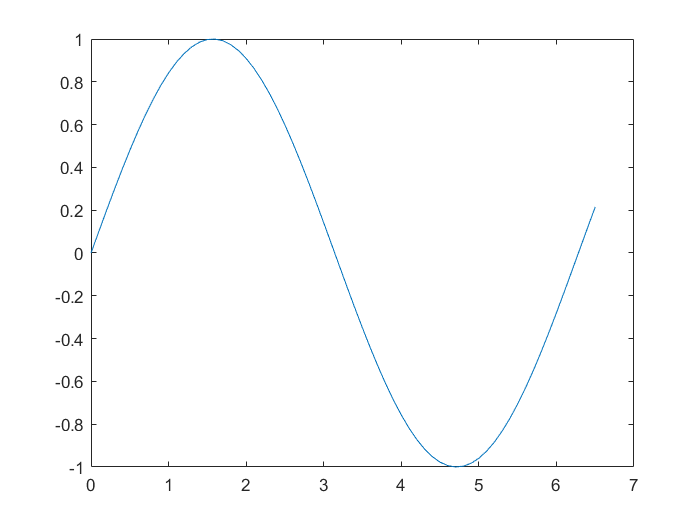

plot(t,sigx); 

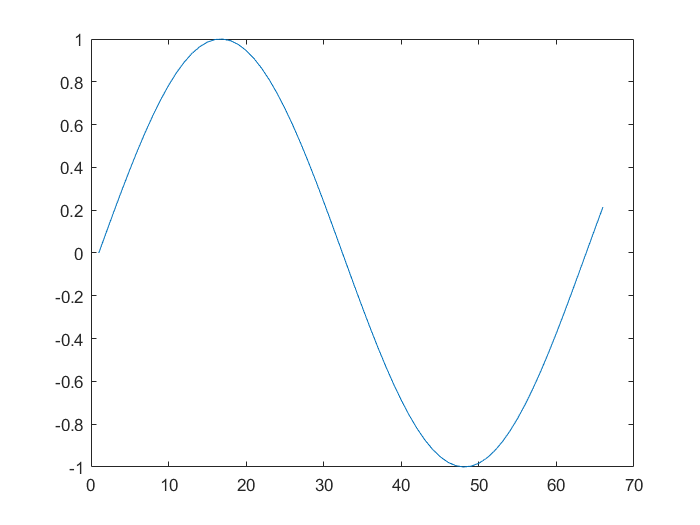

plot(sigx); 

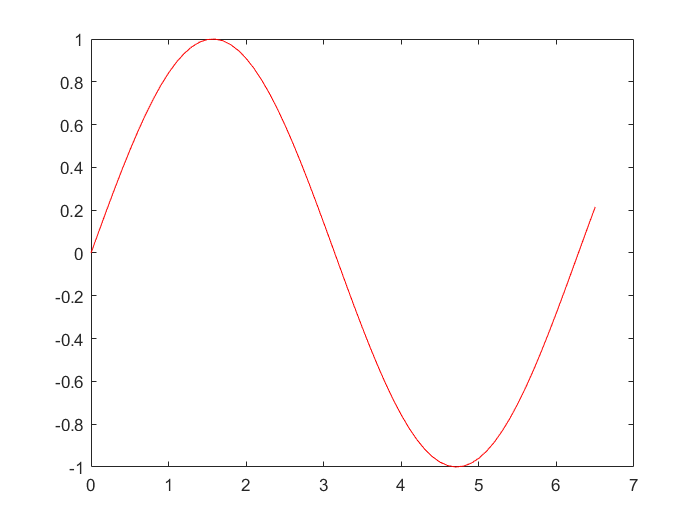

plot(t,sigx, '-r'); 

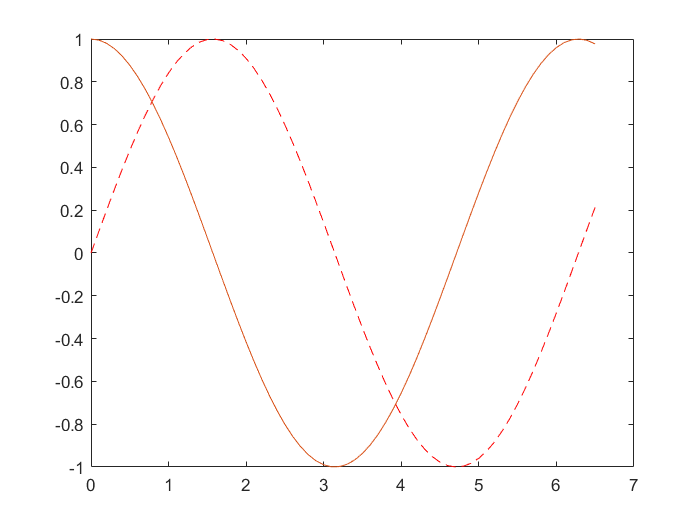

plot(t,sigx,'--r',t,sigy); 

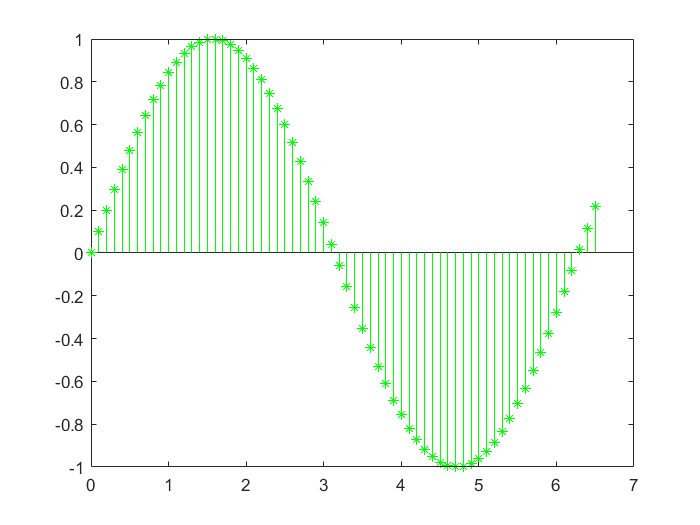

stem(t,sigx,'* g')

## fplot （不做要求）

syms x
y = sin(2*pi*x)

$$y = \sin\left(2\,\pi \,x\right)$$

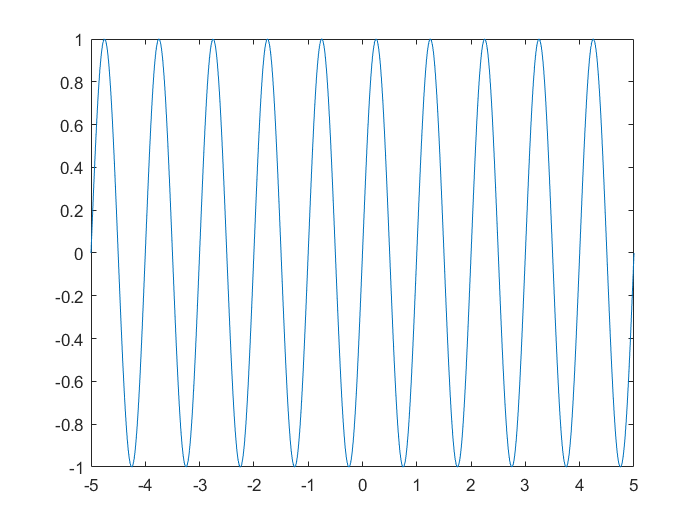

fplot(x,y); 

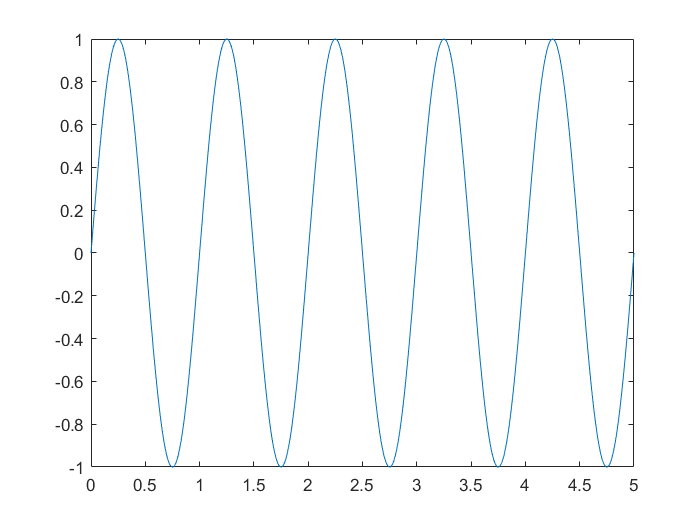

fplot(y,[0 5]);

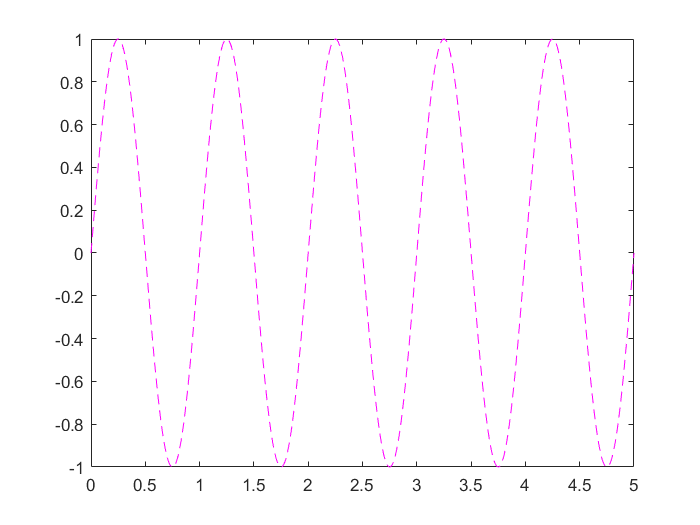

fplot(x,y,[0 5],"Color",'m',"LineStyle","--")

## subplot

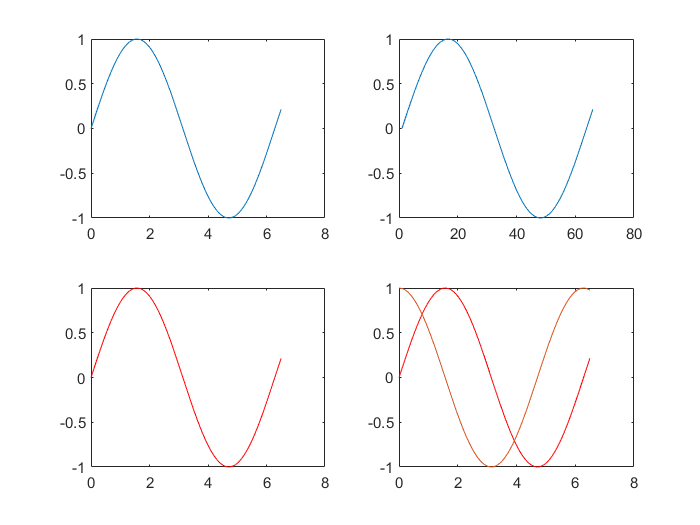

clf;
subplot(2,2,1); plot(t,sigx);
subplot(2,2,2); plot(sigx);
subplot(2,2,3); plot(t,sigx,'-r');
subplot(2,2,4); plot(t,sigx,'-r',t,sigy);

subplot merge area（合并区域绘图）

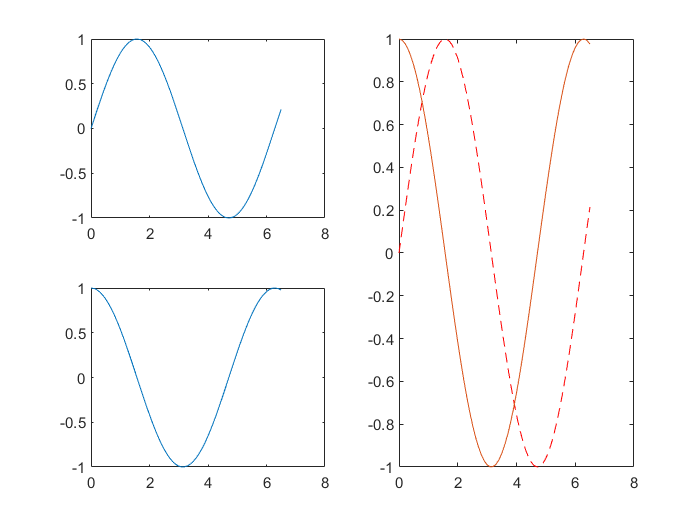

clf;
subplot(2,2,1); plot(t,sigx);
subplot(2,2,3); plot(t,sigy);
subplot(2,2,[2 4]); plot(t,sigx,'--r',t,sigy);

## Label & Title & Legend（绘图标注）

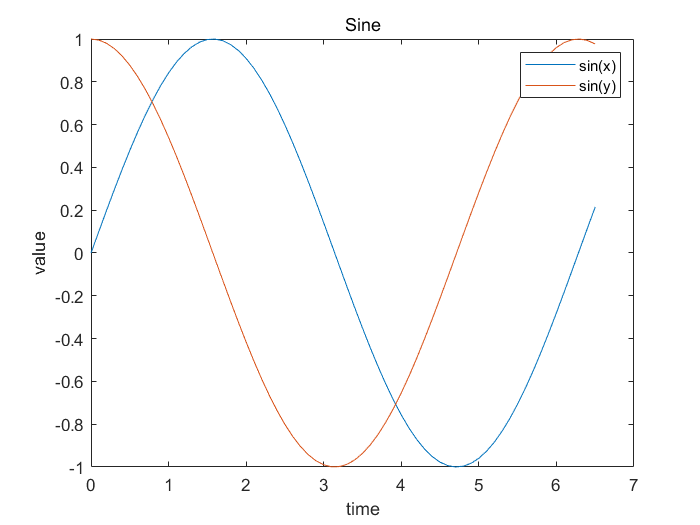

clf;
plot(t,sigx,t,sigy);
title('Sine');
xlabel('time');
ylabel('value');
legend('sin(x)','sin(y)');

## Range（设定图片显示范围）

When several pictures have a comparative relationship, the display range should be set to be consistent.

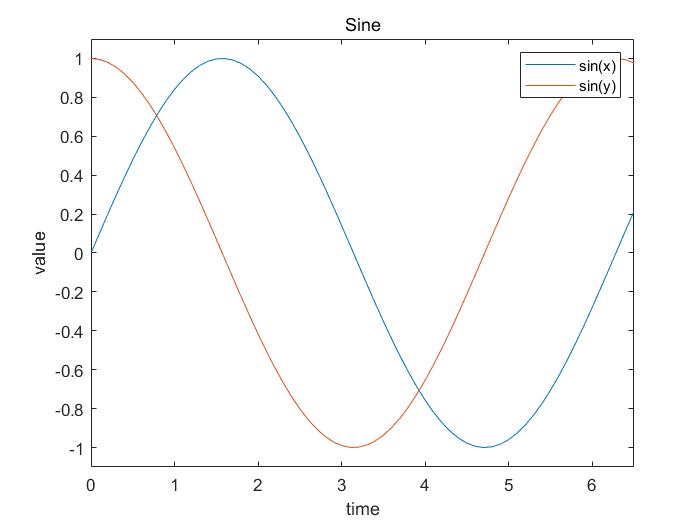

axis([0 6.5 -1.1 1.1]);

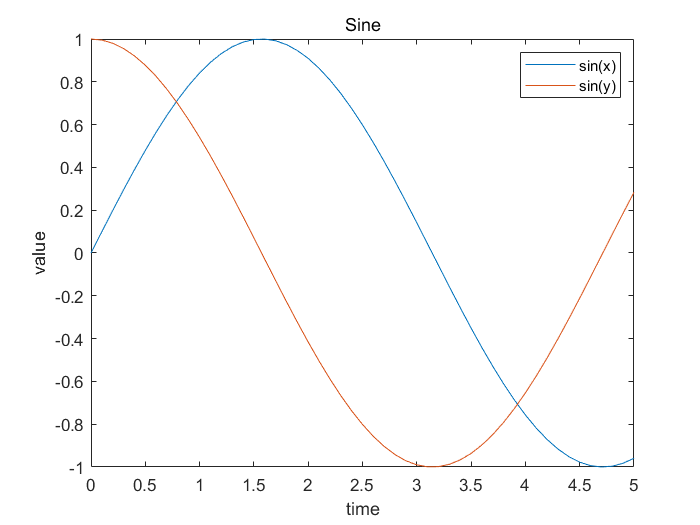

xlim([0 5]);
ylim([-1 1]);

## Grid（网格）

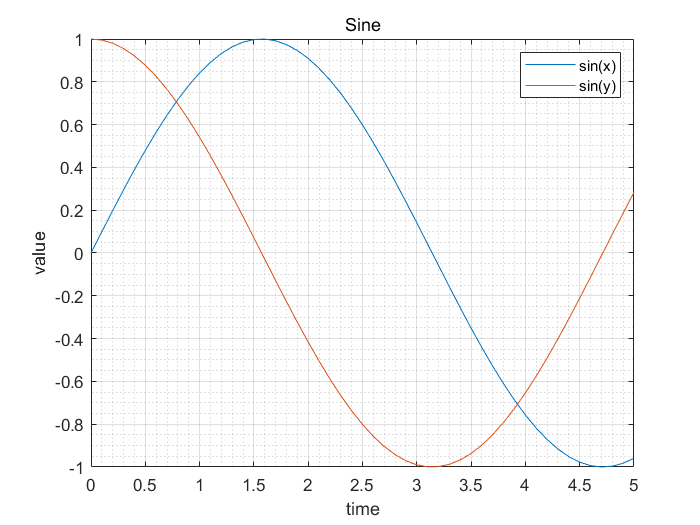

grid on;
grid minor;

# Functions to Generate Elementary Signal（数值法及符号法创建信号）

Both methods is ok：sin、cos、sinc、exp、heaviside、diract（两种方法均可的函数）

### sin(t)、cos(t)    

###  (三角函数，多用途)

t：time axis（时间轴）

Radian frequency and radian is used for **cos** and** sin**.

（Matlab中三角函数使用的是角频率和弧度值，不是频率和角度值）

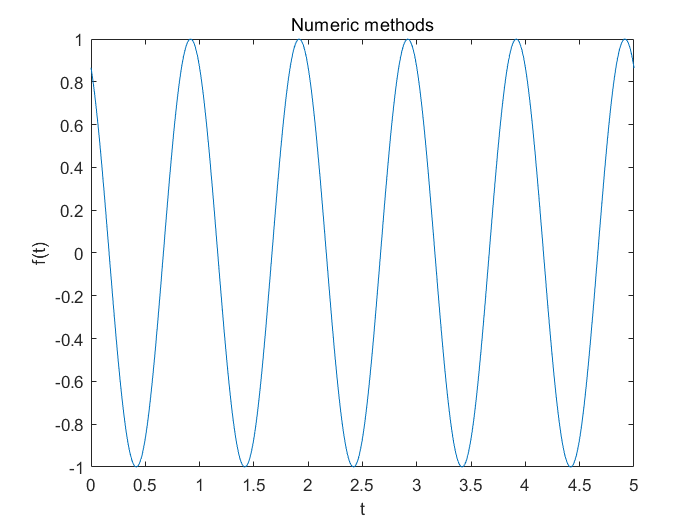

clear; clf;
A = 1;
w = 2*pi;
phi = pi/6;
% Numeric methods
t = 0:0.01:10;
fn = A*cos(w*t+phi);
plot(t,fn); axis([0 5 -1 1]); 
xlabel("t");ylabel("f(t)");title('Numeric methods');

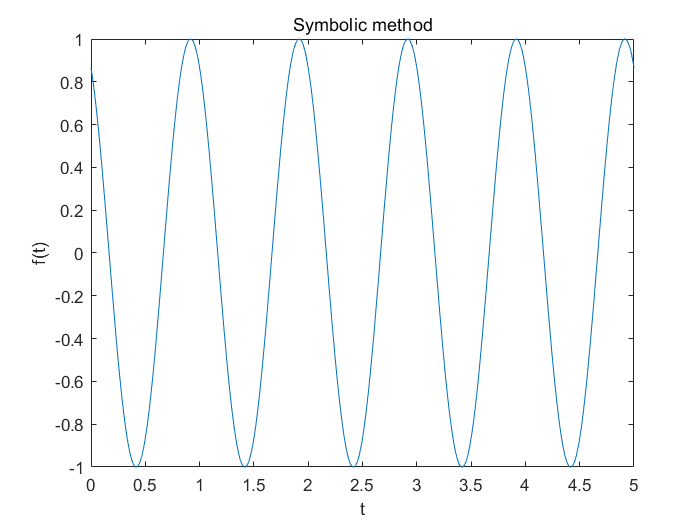

% Symbolic methods （不做要求）
syms ts
fs = A*cos(w*ts+phi);
fplot(fs); axis([0 5 -1 1]); 
xlabel("t");ylabel("f(t)");title('Symbolic method');

### Sampling：sinc(t)   

### （采样信号）

t：time axis（时间轴）

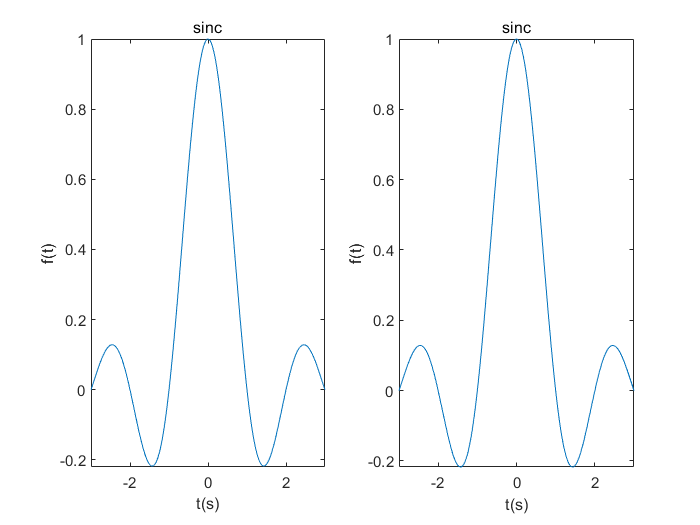

clear; clf;
% Numeric methods
t = -3:0.01:3;
ft = sinc(t);
subplot(1,2,1);plot(t,ft); axis([-3 3 -0.22 1])
title('sinc'); xlabel('t(s)');ylabel('f(t)');

% Symbolic methods （不做要求）
syms x
y =sinc(x);
subplot(1,2,2);fplot(y,[-3 3])
title('sinc'); xlabel('t(s)');ylabel('f(t)');

### Exponential：A*exp(a*t)  

### （指数信号）

t：time axis（时间轴）

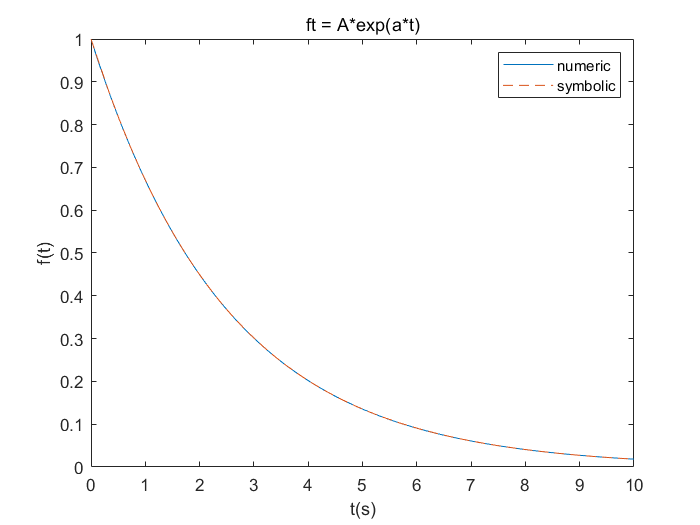

clear; clf;
A = 1;  a = -0.4;
% Numeric methods
t = 0:0.01:10;
ft = A*exp(a*t);
plot(t,ft); hold on;
% Symbolic methods
syms x
y = A*exp(a*x);
fplot(x,y,[0 10],'--'); hold off;
title('ft = A*exp(a*t)'); xlabel('t(s)');ylabel('f(t)');legend("numeric","symbolic");

### **Aperiodic Triangle**： tripuls(t,w,s) 

### （ 三角（形）信号）

t：time axis（时间轴）

w：The width of the base of the triangle, centered at 0.（三角形的底边宽度，以0为中心）

s：Vertex position, range: [-1 1]. （顶点位置，  范围： [-1 1]）

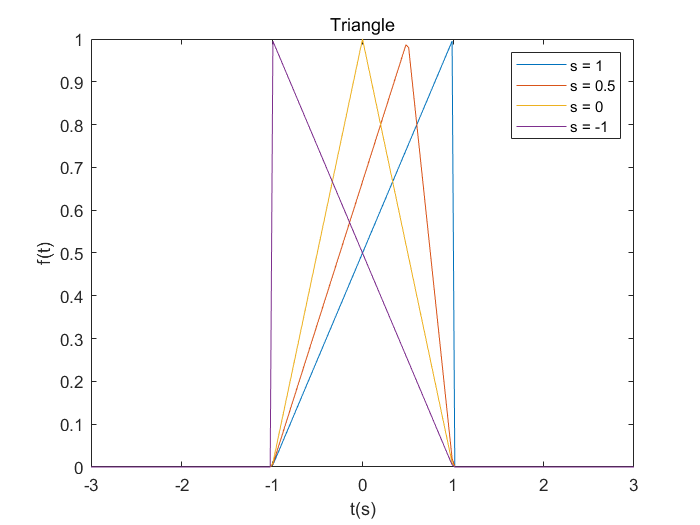

clear; clf;
t = -3:0.03:3;
ft1 = tripuls(t,2,1);
ft2 = tripuls(t,2,0.5);
ft3 = tripuls(t,2,0);
ft4 = tripuls(t,2,-1);
plot(t,ft1,t,ft2,t,ft3,t,ft4); 
title('Triangle'); xlabel('t(s)');ylabel('f(t)');
legend('s = 1','s = 0.5','s = 0 ','s = -1')

### **Sawtooth or triangle wave**：sawtooth(t,xmax)   

### （锯齿波）

t：time axis（时间轴）

xmax：Vertex position, range: [0 1], periodic: 2pi（ 顶点位置， 范围：[0 1]，周期：2pi）

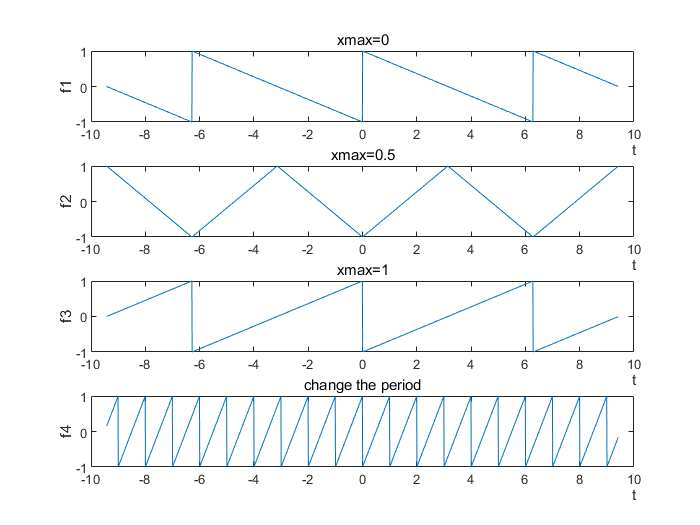

clear; clf;
t = -3*pi:0.01:3*pi;
ft1 = sawtooth(t,0);
ft2 = sawtooth(t,0.5);
ft3 = sawtooth(t,1);
subplot(4,1,1); plot(t,ft1); title('xmax=0'); xlabel('t','position',[10 -1.5 0]);ylabel('f1');
subplot(4,1,2); plot(t,ft2); title('xmax=0.5'); xlabel('t','position',[10 -1.5 0]);ylabel('f2');
subplot(4,1,3); plot(t,ft3); title('xmax=1'); xlabel('t','position',[10 -1.5 0]);ylabel('f3');

ft4 = sawtooth(2*pi*t,1);
subplot(4,1,4); plot(t,ft4); title('change the period'); xlabel('t','position',[10 -1.5 0]);ylabel('f4');

### **Aperiodic Rectangle**：rectpuls(t,w)  

### （矩形（窗）信号）

t：time axis（时间轴）

w：rectangle width（矩形宽度）

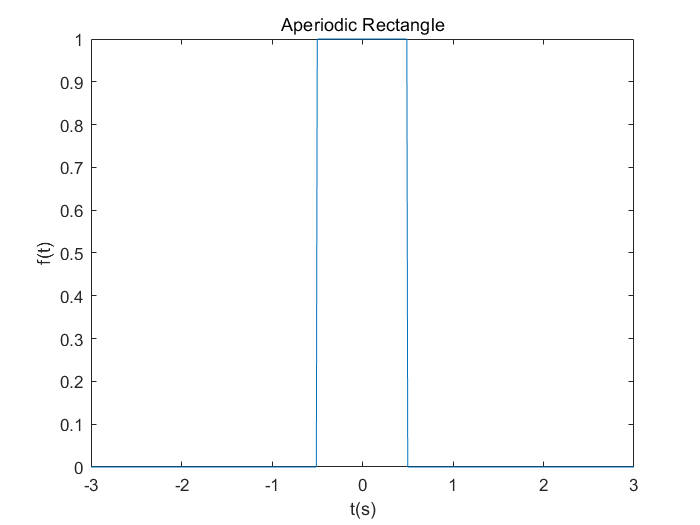

clear; clf;
t = -3:0.01:3;
ft = rectpuls(t,1);
plot(t,ft);
title('Aperiodic Rectangle'); xlabel('t(s)');ylabel('f(t)');

### **Square Wave**：square(t,d)  

### （方波信号）

t：time axis（时间轴）

d：Duty cycle, the proportion of the positive part of the signal, range: [0 100]（占空比，信号为正的部分所占比例，范围：[0 100]）

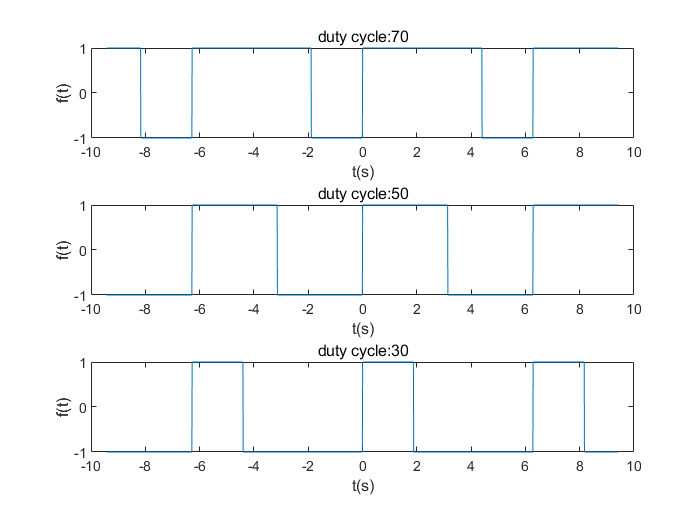

t = -3*pi:0.01:3*pi;
ft = square(t,70);
subplot(3,1,1); plot(t,ft); title('duty cycle:70'); xlabel('t(s)');ylabel('f(t)');
ft = square(t,50);
subplot(3,1,2); plot(t,ft); title('duty cycle:50'); xlabel('t(s)');ylabel('f(t)');
ft = square(t,30);
subplot(3,1,3); plot(t,ft); title('duty cycle:30'); xlabel('t(s)');ylabel('f(t)');

### **Step Function**：heaviside(t)  

### （阶跃信号）

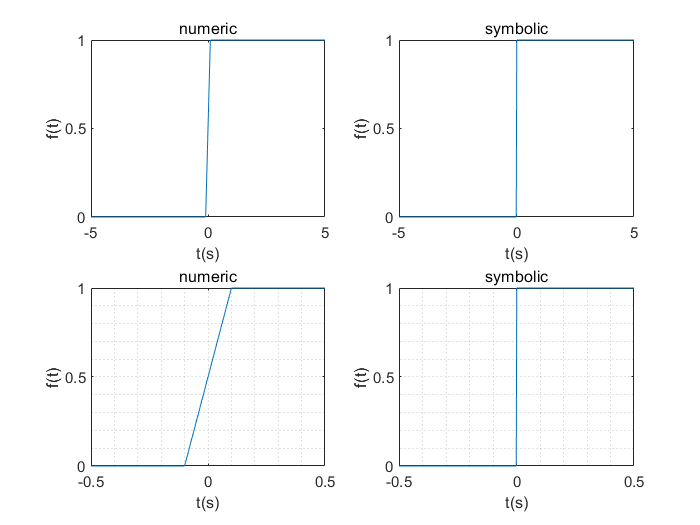

clear;clf;
t = -5:0.1:5;
ft = heaviside(t);

syms x
y = heaviside(x);

subplot(2,2,1); plot(t,ft); title('numeric');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,2); fplot(x,y); title('symbolic');xlabel('t(s)');ylabel('f(t)');
subplot(2,2,3); plot(t,ft); axis([-0.5 0.5 -inf inf]); title('numeric');xlabel('t(s)');ylabel('f(t)'); grid minor;
subplot(2,2,4); fplot(x,y,[-0.5 0.5]); title('symbolic');xlabel('t(s)');ylabel('f(t)');grid minor;

# Signal Operation（信号运算）

## Dot Operation & Matrix Operation

The difference between the operation with and without dot.

clear; clf;
b = ones(3,3)      % 1*5 matrix

b =      1     1     1
     1     1     1
     1     1     1


c = 2*ones(3,3)      % 1*5 matrix

c =      2     2     2
     2     2     2
     2     2     2


b*c

ans =      6     6     6
     6     6     6
     6     6     6


b.*c

ans =      2     2     2
     2     2     2
     2     2     2


## Differential and Integral（微分和积分）

### Differential（微分/差分）

diff(S, 'V', N)

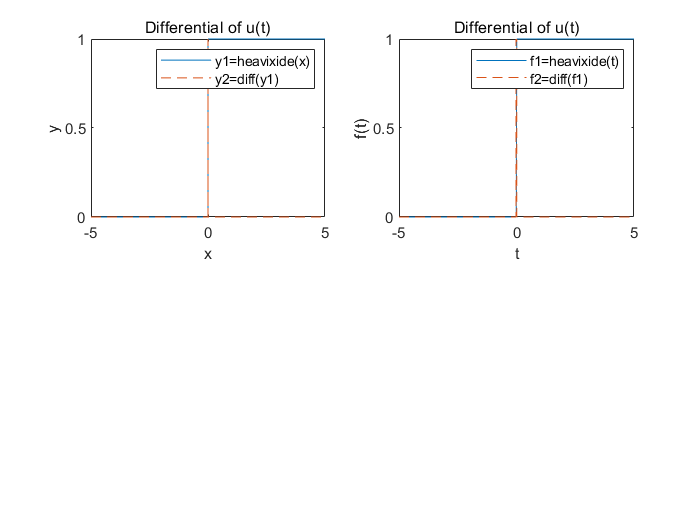

clear; clf;
% symbolic method
syms x
y1 = heaviside(x);
y2 = diff(y1,x);
subplot(2,2,1);
fplot(y1);hold on;
fplot(sign(y2),'--'); hold off; 
legend("y1=heavixide(x)","y2=diff(y1)")
xlabel("x"); ylabel('y');title('Differential of u(t)')

% numeric method
dt = 0.01;
t = -5:dt:5;
f1 = heaviside(t);
f2 = diff(f1)/dt;
subplot(2,2,2);
plot(t,f1);hold on;
plot(t(1:end-1),f2,"--");hold off;
axis([-5 5 0 1]);
legend("f1=heavixide(t)","f2=diff(f1)")
xlabel("t"); ylabel('f(t)');title('Differential of u(t)')

### Integral（积分）

Indefinite integral（不定积分）:

symbolic method：int(S, v)

numeric method：cumtrapz(t, y)

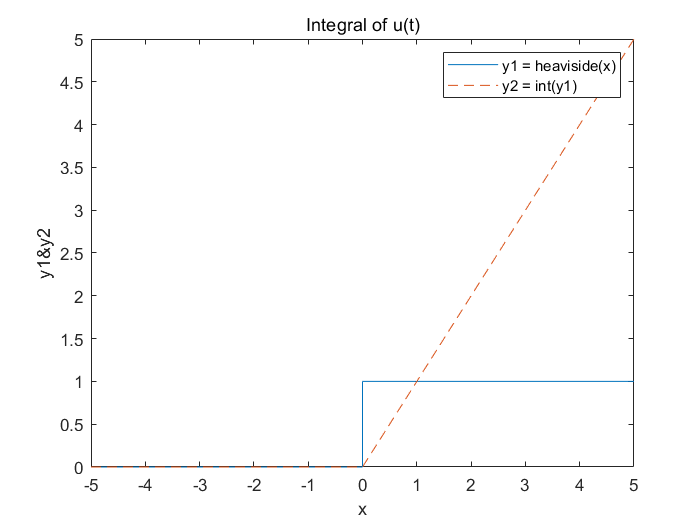

clear; clf;
% symbolic method
syms x
c = 0;
y1 = heaviside(x);
y2 = int(y1,x)+c;
fplot(y1);hold on;
fplot(y2,'--');hold off;
legend('y1 = heaviside(x)','y2 = int(y1)');
xlabel('x');ylabel('y1&y2');title('Integral of u(t)')

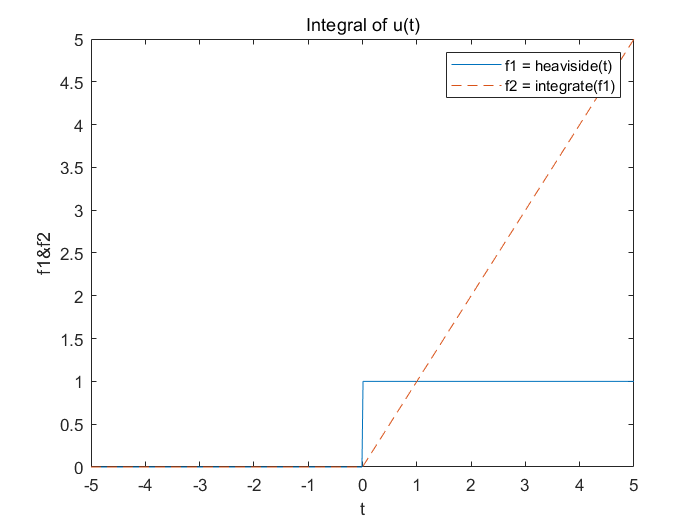

% numeric method
dt = 0.01;
t = -5:dt:5;
f1 = heaviside(t);
f2 = cumtrapz(t, f1)+c;
plot(t,f1,t,f2,'--');
legend('f1 = heaviside(t)','f2 = integrate(f1)');
xlabel('t');ylabel('f1&f2');title('Integral of u(t)')

definite integral（定积分）:

symbolic method：int(S, v, a, b)

numeric method：trapz(t, y)

clear; clf;
% symbolic method
syms t1
int(heaviside(t1),-1,2)

$$ans = 2$$


% numeric method
t2 = -1:0.01:2;
trapz(t2,heaviside(t2))

ans = 2

# Programing Structure（结构）

## Loop（循环）

% for loop
a = zeros(1,10);
for i = 1:10
    a(i) = i;
end
a

a =      1     2     3     4     5     6     7     8     9    10


## Branch（分支）

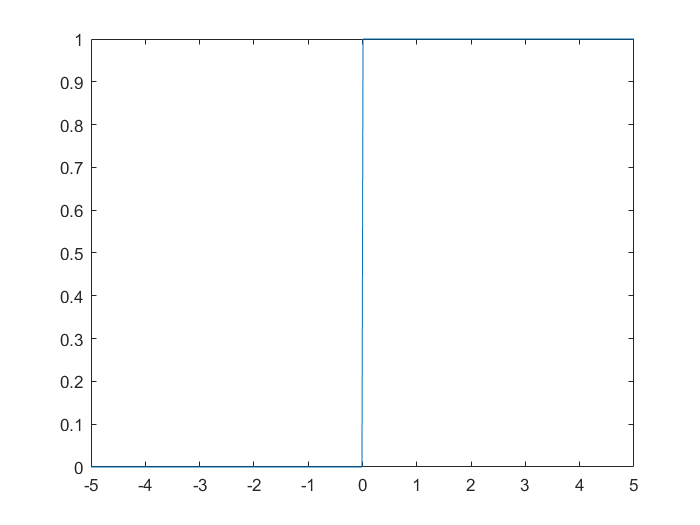

% if-else-end
t = -5:0.01:5;
f = zeros(1,length(t));
for i=1:length(t)
    if t(i) < 0
        f(i) = 0;
    elseif t(i) == 0
        f(i) = 0.5;
    else
        f(i) = 1;
    end
end
clf
plot(t, f);